# Tabletop problem for study 

This livescript builds a tabletop planning problem that consists of 

- a width x height world grid.

- an agent, can be a robot, satellite, uav, etc. The agent can move (up, down, left, right) or perform other actions, which deplete the battery

- a discretized battery model (4 states, [1,2,3,4], 1 is fully charged to steady state, 2 is steady state, 3 is steady to decline, 4 is decline - end of charge. [wip] --> moving one "normal" square depletes 3% soc, moving one "bad" square depletes 5% soc, taking a picture depletes 1%, transmitting the picture depletes 2% (some of this isn't implemented yet)

## General Setup

- The map

width = 4;
height = 3;

% start location
start = [1,1];
finish = start;

% location prototype
location.type = "normal"; 
location.label = "";

% map is a matrix of structs
map = repmat(location, width, height);

- The agent

agent.type = "robot";
agent.location = start;
agent.distance = 0;
agent.direction = '^';
agent.soc = 100;
agent.locationType = location.type;
agent.cumulativeReward = int16(0);

- actions (move up, down, left, right, observe, transmit

actions = ['^', 'v', '<', '>', 'o', 't'];

## Keep track of State

state.location = agent.location;
state.battery = 1;
state.achieved1 = false;
%state.achieved2 = false;

## The world grid

- add "points of interest"

- References are hard-coded throughout, however their location values, lengths, and names can be changed

- Update the locations here

poi.start = agent.location;
poi.objectives = [4,3];% [8,5; 2,6];
poi.pitfalls = [4,2];%[2,5; 4,1; 6,2; 8,2; 6,6; 6,7; 7,7];
poi.blocks = [2,2];%[1,4; 4,3; 6,3; 5,3; 2,2; 5,4; 5,5];

- update location names here

map(poi.start(1), poi.start(2)).type = "start";
for i=1:1%(length(poi.objectives))
    map(poi.objectives(i,1), poi.objectives(i,2)).type = "objective";
    map(poi.objectives(i,1), poi.objectives(i,2)).label = sprintf("O-%d", i);
end

for i=1:1%(length(poi.pitfalls))
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).type = "pitfall";
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).label = sprintf("P-%d", i);
end
for i=1:1%(length(poi.blocks))
    map(poi.blocks(i,1), poi.blocks(i,2)).type = "block";
end

### Visualize the grid world

- show location of robot and objects 

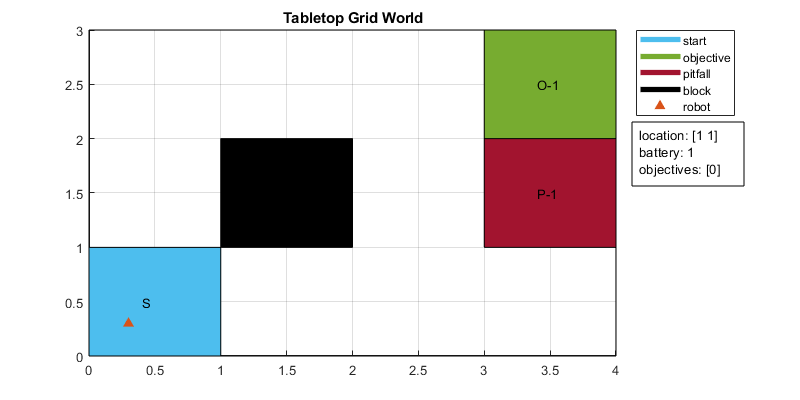

f1 = visualizeGridWorld(1, map, poi, state, agent);
title("Tabletop Grid World");

### [optional] Move the robot, and revisualize

- The robot cannot travel off of the grid or on a black spot

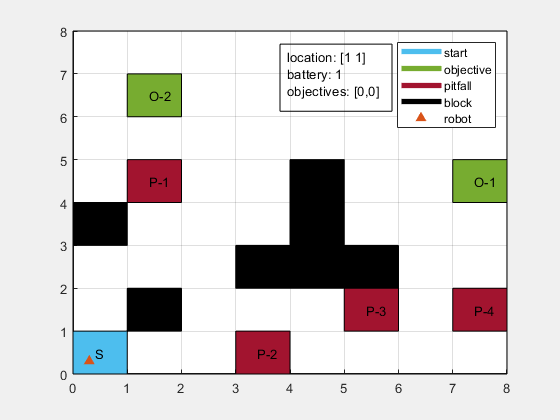

agent = moveAgent(agent, '>', 1, map, poi);
state = update_state(state, agent, map);
f2 = visualizeGridWorld(2, map, poi, state, agent);

### [optional] Robot Teleop

- reads arrow keys, q to quit (press enter to close pop up figure)

- run above block to generate figure 2

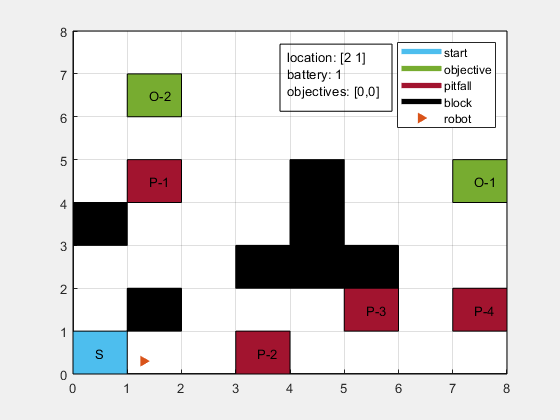

teleop(agent, 2, map, poi, state);

## Shortest path test

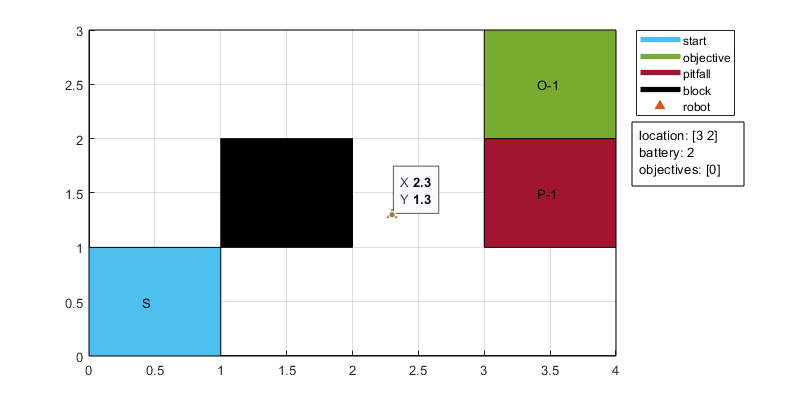

G = convert2graph(map, "block", "pitfall");
start_ID = 1;
obj1_ID = 8;%40;
%obj2_ID = 58;

[P, d, edgepath] = shortestpath(G, start_ID, obj1_ID);
dirs = get_path_directions(map, P);

%reset agent and state 
state.location = agent.location;
state.battery = 1;
state.achieved1 = false;
state.achieved2 = false;

agent = set_agent(agent, map, [1,1], 0, '^', 100, 1, 0);
for i=1:length(dirs)
    f3 = visualizeGridWorld(3, map, poi, state, agent);
    if i < length(dirs)
        agent = moveAgent(agent, dirs(i), 1, map, poi);
        state = update_state(state, agent, map); %rename this function
    end
    pause(.3);
end

## MDP Formulation

% states could even be string encodings of multiple variables
states = ["s1", "s2"];

% actions, like states, can be anything
actions = ["a1", "a2"];

% the rewards of the states should encode the agents real-world objective(s)
rewards = [3, -1];

% initialize the states value aka utility to its reward
values = rewards(:)';

% the transition function must be manually encoded with probabilities provided in the 
% problem definition (or estimated given a sequence of states - more on that later)
T(1,1,1) = 0;
T(1,1,2) = .5;
T(1,2,1) = 1.0;
T(1,2,2) = 0;
T(2,1,1) = 1.0;
T(2,1,2) = .5;
T(2,2,1) = 0;
T(2,2,2) = 1.0;

% gamma is the discount factor, or the relative importance of the reward of the 
% next step (the next-next step is gamma^2, next-next-next is gamma^3, ...)
gamma = .5;

% beta is the minimum amount of improvement need between iterations to
% continue the value iteration algorithm
beta = .005;

### Value Iteration

old_values = ones(1, length(rewards))*-999;
stopping_criteria = .005;
policy.states = states;
policy.actions = repmat("", 1, length(states));
i = 1;
disp(values);

     3    -1



while(abs(sum(values) - sum(old_values)) > beta)
    old_values = values;
    for j=1:length(states)
        vals = zeros(1, length(actions));
        for n=1:length(actions)
            for k=1:length(states)
                vals(n) = vals(n) + T(k,j,n)*values(k);
                if j == 1 && n == 1
                    debug(i,j,k,length(states), n, T(k,j,n), values(k));
                end
            end
        end
        [m,idx] = max(vals);
        
        values(j) = rewards(j) + gamma * m;
        policy.actions(j) = actions(idx);
        
    end
    i = i + 1;
end

i: 1	j: 1	n: 1	T(k,j,n): 0.000	V(k): 3.000  + T(k,j,n): 1.000	V(k): -1.000
i: 2	j: 1	n: 1	T(k,j,n): 0.000	V(k): 3.500  + T(k,j,n): 1.000	V(k): 0.750
i: 3	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.063  + T(k,j,n): 1.000	V(k): 1.031
i: 4	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.273  + T(k,j,n): 1.000	V(k): 1.137
i: 5	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.353  + T(k,j,n): 1.000	V(k): 1.176
i: 6	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.382  + T(k,j,n): 1.000	V(k): 1.191
i: 7	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.393  + T(k,j,n): 1.000	V(k): 1.197
i: 8	j: 1	n: 1	T(k,j,n): 0.000	V(k): 4.397  + T(k,j,n): 1.000	V(k): 1.199


disp("stopping criteria met. State values have been permanently assigned.");

stopping criteria met. State values have been permanently assigned.


for i = 1:length(states)
    fprintf("%c*(%s) = %s\n", 960, policy.states(i), policy.actions(i));
end

π*(s1) = a2
π*(s2) = a1


disp(values);

    4.3991    1.1995



function debug(i, j, k, K, n, t, v)
    if(k == 1)
        fprintf("i: %.d\tj: %d\tn: %d\tT(k,j,n): %.3f\tV(k): %.3f ", i, j, n, t, v);
    else
        fprintf("T(k,j,n): %.3f\tV(k): %.3f", t, v);
    end
    if(k ~= K)
        fprintf(" + ");
    else
        fprintf("\n");
    end
end